## Derivatives

This notebook includes some exercises to calculate derivates numerically and symbolically in MATLAB. Prepared for EAS Practical Coding and Math course at Georgia Tech.

### Numerical Derivatives

First lets define a function $y=e^{-x} \;\sin \left(x^2 \right)$ which is annoying, but not impossible, to analytically differentiate

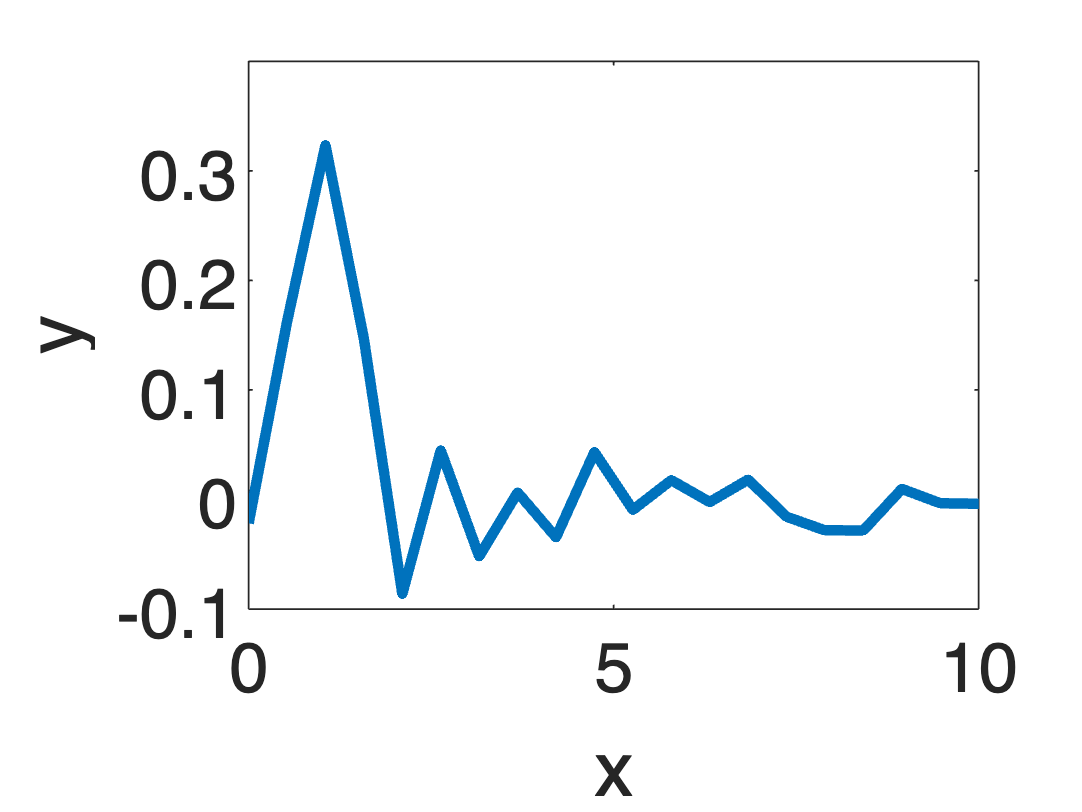

x = linspace(0,10,20);
y = exp(-x).*sin(x.^2) + 0.02.*randn(1,20);
plot(x,y,'linewidth',3)
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

One simple way to calculate the derivative is using diff, which calculates the running difference of order n (i.e. order of the derivative)

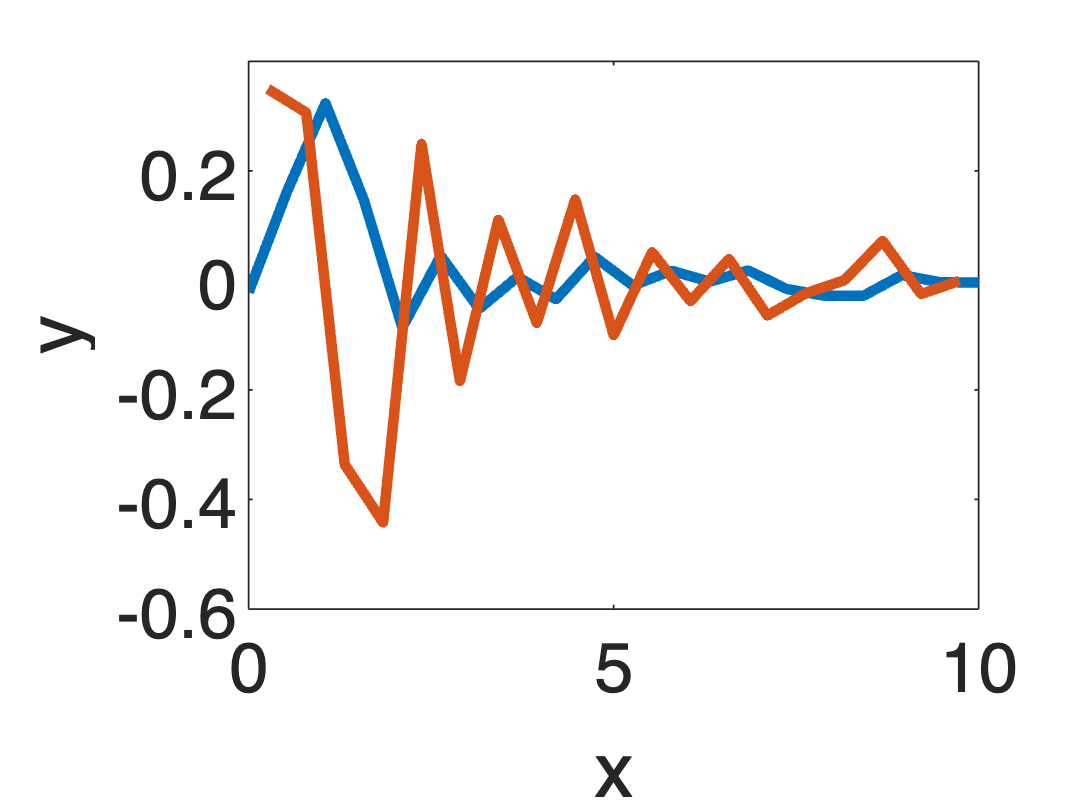

dydx = diff(y,1)./diff(x,1);
plot(x,y,'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

xmid = (x(1:end-1)+x(2:end))/2; %xmid is the midpoint value of x on each interval
plot(xmid,dydx,'linewidth',3) %note that we need to modify x which has one more element than dydx

We can also take the second order derivative $\frac{d^2 y}{dx^2 }$ this way

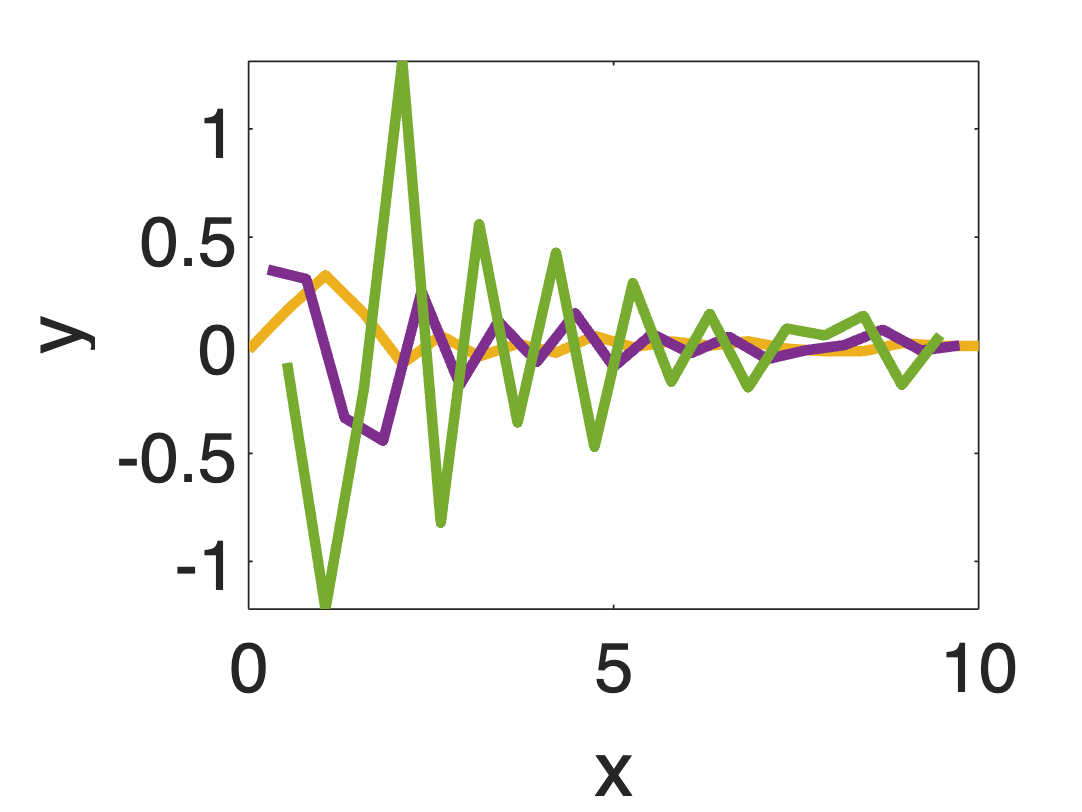

d2ydx2 = diff(y,2)./(diff(xmid,1).^2);
plot(x,y,'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

xmid = (x(1:end-1)+x(2:end))/2; %xmid is the midpoint value of x on each interval
plot(xmid,dydx,'linewidth',3) %note that we need to modify x which has one more element than dydx
plot(x(2:end-1),d2ydx2,'linewidth',3) %note that we need to modify x which has one more element than dydx

So we run into a problem because this is a lousy way of calculating gradients (prone to errrors).

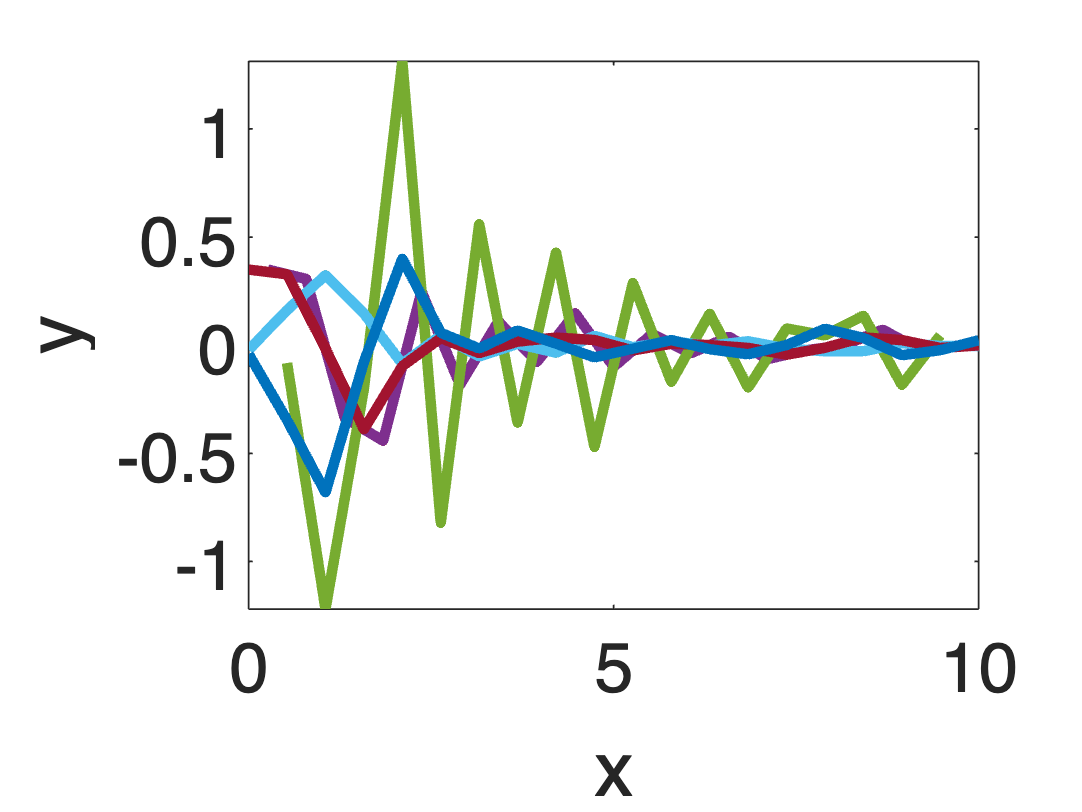

dydx = gradient(y, x(2)-x(1));
d2ydx2 = gradient(gradient(y, diff(x(1:2))),diff(x(1:2)));
plot(x,y,'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

xmid = (x(1:end-1)+x(2:end))/2; %xmid is the midpoint value of x on each interval
plot(x,dydx,'linewidth',3) %note that we need to modify x which has one more element than dydx
plot(x,d2ydx2,'linewidth',3) %note that we need to modify x which has one more element than dydx

### Symbolic/analytical derivatives

To use the symbolic toolbox in MATLAB first you need to define a particular function as being a symbolic data type

syms f(x)
f(x) = exp(-x)*sin(x^2)

$$f(x) = \sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}$$

Then you can use diff on the symbolic function, but MATLAB knows to do this anlaytically, rather than numerically

Df = diff(f,x) %this means differential f with respect to x

$$Df(x) = 2\,x\,\cos\left(x^{2}\right)\,{\mathrm{e}}^{-x}-\sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}$$

And we can easily take a second derivative as well

Df2 = diff(f,x,2)

$$Df2(x) = 2\,\cos\left(x^{2}\right)\,{\mathrm{e}}^{-x}+\sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}-4\,x\,\cos\left(x^{2}\right)\,{\mathrm{e}}^{-x}-4\,x^{2}\,\sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}$$

fplot is the MATLAB function for plotting symbolic functions

hold off

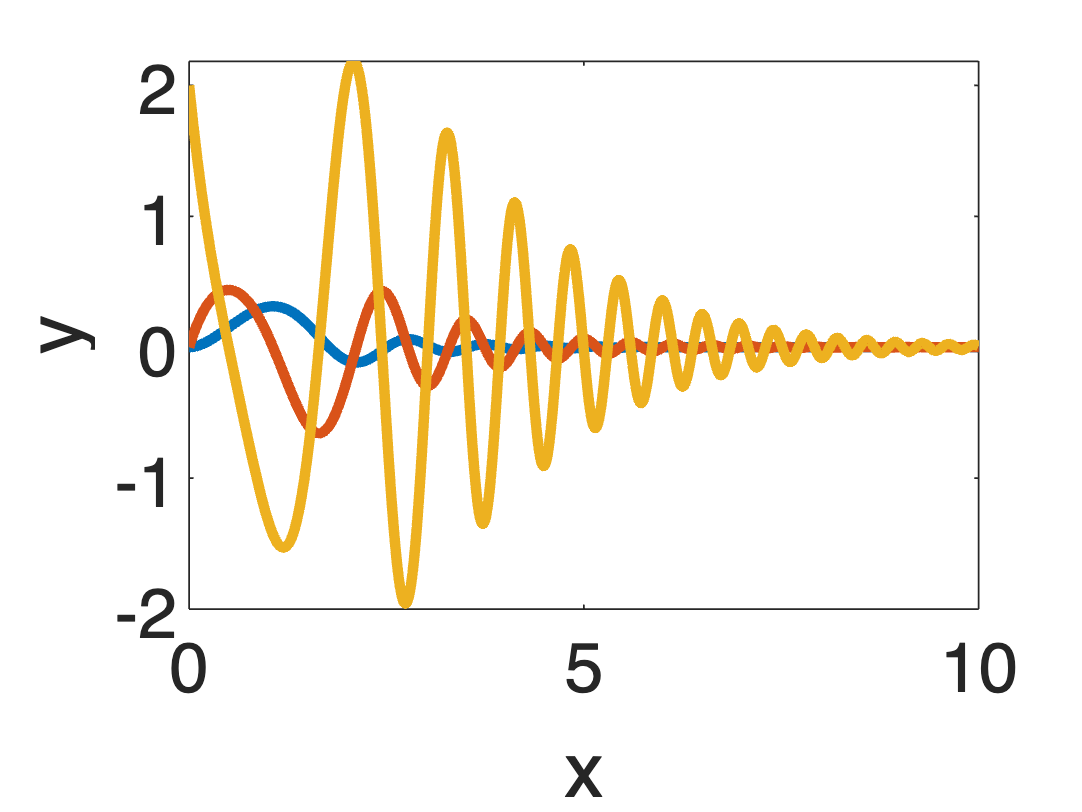

fplot(f,[0 10],'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

fplot(Df,[0 10],'linewidth',3);
fplot(Df2,[0 10],'linewidth',3);